# Basic Exploration of Analysis of Datalogger

Read the data into a MATLAB "table" object

A MATLAB "table" is equivalent to a Pandas DataFrame in Python.

T = readtable("2023-10-25 Office.txt");

Plot the magnitude of the acceleration components over time.

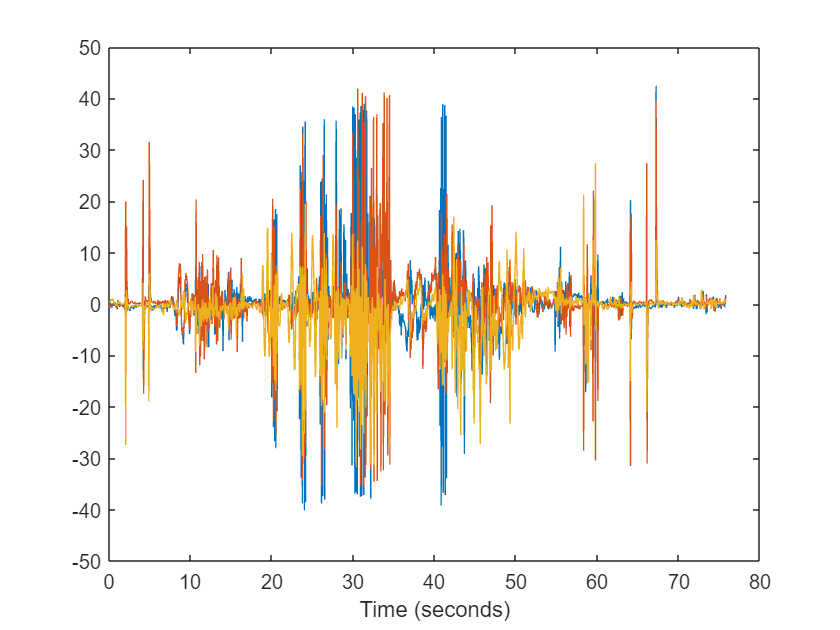

T.secs = double(cumsum(T.deltat)) / 1000;
plot(T.secs, T.AcX);
hold on
plot(T.secs, T.AcY);
plot(T.secs, T.AcZ);
hold off
xlabel("Time (seconds)");